% Unsupervised learning model for calculating midget ganglion cells receptive
% field responses to the edges formed by adjacent pixels in an RGB image,
% and determining the correlation between their response patterns

% File Name: ImageCorr_Unsupervised

% Livescript originally written December, 6, 2021
% Last updated June 12, 2022

% Used for the paper "How we see black and white: the role of midget
% ganglion cells" submitted to Frontiers Neuroanatomy

## Reset workspace

% Clear all existing variables and close all open windows

clear;
close all;

## Establish Main Peramaters

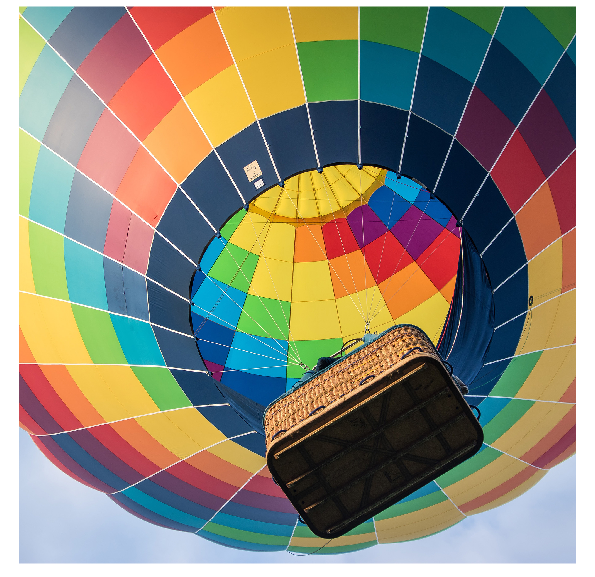

WL = (400:5:700); % Wavelengths from 400 to 700 in 5 nm steps
age = 0; % Zero will use the Stockman Lens. All other ages use Van Norren age-based lens.
LM_Ratio = [2,1]; % Ratio of L to M cones. "Average" in population is 2:1

%Import Image

Img_RAW = imread('balloon.jpg'); % Select RGB image to import
imshow(Img_RAW) % Show imported image


if size(Img_RAW,3) ~= 3 % If image is single-dimention grayscale TIFF, convert to 3D array
    Img_RAW=cat(3,Img_RAW, Img_RAW, Img_RAW);
end

Img_RAW = double(Img_RAW); % convert to double
Img_RGB = Img_RAW./255; % normalize RGB values between 0 and 1


% Define photopigment peaks and optical density

PhotoPeaks = [419, 530, 559]; % S, M and L photopigment peaks
OpticalD = [.40, .22, .35]; % S, M, and L optical densities

% Establish Image Dimensions

X=size(Img_RGB,1);
Y=size(Img_RGB,2);
Z=size(Img_RGB,3);

% Load LCD Screen Primaries (iPhone 5, sRGB)

iPhone_RGB = readmatrix('LCD_Primaries.xlsx', 'Range', 'B68:D128');

yel = iPhone_RGB(:,1)+iPhone_RGB(:,2);
wt = iPhone_RGB(:,1)+iPhone_RGB(:,2)+iPhone_RGB(:,3);

iPhone_RGBYW=[iPhone_RGB(:,1), iPhone_RGB(:,2), iPhone_RGB(:,3), yel, wt];

% Equal Energy in Quanta

EEquanta=zeros(1,length(WL));

for x=1:length(WL)
    EEquanta(x)=WL(x)/700;
end

## Calculate Cone Opponent Gains and Second Stage Mechanisms

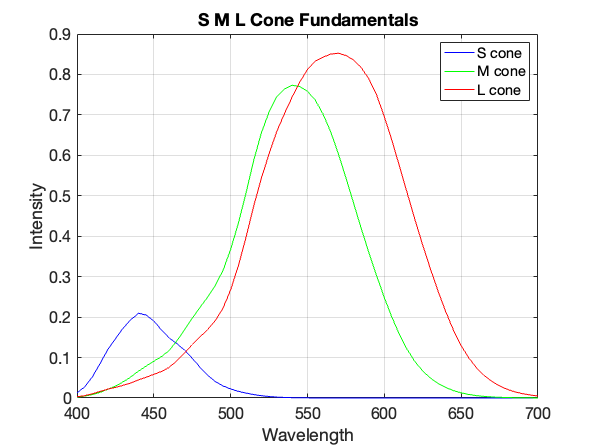

% Generate S, M, L cone fundamentals

S_spec=spec(PhotoPeaks(1),OpticalD(1), age); % S-cone spectrum
M_spec=spec(PhotoPeaks(2),OpticalD(2), age); % M-cone spectrum
L_spec=spec(PhotoPeaks(3),OpticalD(3), age); % L-cone spectrum
LM_spec = L_spec*(LM_Ratio(1)/sum(LM_Ratio))+ M_spec*(LM_Ratio(2)/sum(LM_Ratio)); % L+M surround spectrum

% Plot spectral sensitivity curves

spec_plot=figure;
spec_plot.Position = [1080 540 1200 900];

spec_plot = plot(WL,S_spec,'b-');
hold on
grid on
plot(WL,M_spec,'g-')
plot(WL,L_spec,'r-')
xlim([400,700])
title('S M L Cone Fundamentals')
legend('S cone','M cone','L cone','Location','NorthEast')
xlabel('Wavelength')
ylabel('Intensity')
hold off

ax = gca;
ax.FontSize = 16;

## Normalize to EE White

% Calculate requisite gains using Least Squares

options = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt', 'Display', 'off');

x0=[1, 1];
    
gainsLLM=lsqnonlin(@(x)sum((L_spec.*x(1)-LM_spec.*x(2)).*iPhone_RGBYW(:,5)'), x0, [], [], options);

gainsMLM=lsqnonlin(@(x)sum((M_spec.*x(1)-LM_spec.*x(2)).*iPhone_RGBYW(:,5)'), x0, [], [], options);

gainsSLM=lsqnonlin(@(x)sum((S_spec.*x(1)-LM_spec.*x(2)).*iPhone_RGBYW(:,5)'), x0, [], [], options);

% Normalize L, M and S cone responses using calculated gains

L_Norm = L_spec.*gainsLLM(1);
M_Norm = M_spec.*gainsMLM(1);
LM_L_Norm = LM_spec.*gainsLLM(2);
LM_M_Norm = LM_spec.*gainsMLM(2);
L_LM_Norm = L_spec.*gainsLLM(1)-LM_spec.*gainsLLM(2);
M_LM_Norm = M_spec.*gainsMLM(1)-LM_spec.*gainsMLM(2);
S_LM_Norm = S_spec.*gainsSLM(1)-LM_spec.*gainsSLM(2);

% Plot Third Stage Mechanisms

BY = (L_LM_Norm - S_LM_Norm)*-1;
RG = (M_LM_Norm - S_LM_Norm)*-1;

WT_L = L_Norm - LM_L_Norm;
WT_M = M_Norm - LM_M_Norm;

wt_plot=figure;
wt_plot.Position = [1080 540 1200 700];

wt_plot = plot(WL,BY,'b-');
hold on
grid on
plot(WL,RG,'r-')
plot(WL, WT_L, '-k')
plot(WL, WT_M, '-k')
xlim([400,700])
ylim([-0.4, 0.4])
yline(0)
title('Cone Opponent Mechanisms')
legend('Blue/Yellow','Red/Green','Location','NorthEast')
xlabel('Wavelength')
ylabel('Response')
hold off

ax = gca;
ax.FontSize = 16;

## Calculate Responses to LCD Screen Spectra

L_color = zeros(61,5);
M_color = zeros(61,5);
LM_L_color = zeros(61,5);
LM_M_color = zeros(61,5);
L_LM_color = zeros(61,5);
M_LM_color = zeros(61,5);
S_LM_color = zeros(61,5);

for x=1:5
    L_color(:,x) = L_Norm'.*iPhone_RGBYW(:,x);
    M_color(:,x) = M_Norm'.*iPhone_RGBYW(:,x);
    LM_L_color(:,x) = LM_L_Norm'.*iPhone_RGBYW(:,x);
    LM_M_color(:,x) = LM_M_Norm'.*iPhone_RGBYW(:,x);
    L_LM_color(:,x) = L_LM_Norm'.*iPhone_RGBYW(:,x);
    M_LM_color(:,x) = M_LM_Norm'.*iPhone_RGBYW(:,x);
    S_LM_color(:,x) = S_LM_Norm'.*iPhone_RGBYW(:,x);
end

% Calculate Summed Response of Each Cell Type

L_total = sum(L_color,1)/10;
M_total = sum(M_color,1)/10;
LM_L_total = sum(LM_L_color,1)/10;
LM_M_total = sum(LM_M_color,1)/10;
L_LM_total = sum(L_LM_color, 1)/10;
M_LM_total = sum(M_LM_color, 1)/10;
S_LM_total = sum(S_LM_color,1)/10;

% Add Black and Gray to Total Responses

L_total = [L_total(1:4), 0, L_total(5), L_total(5)./2];
M_total = [M_total(1:4), 0, M_total(5), M_total(5)./2];
LM_L_total = [LM_L_total(1:4), 0, LM_L_total(5), LM_L_total(5)./2];
LM_M_total = [LM_M_total(1:4), 0, LM_M_total(5), LM_M_total(5)./2];
L_LM_total = [L_LM_total(1:4), 0, L_LM_total(5), L_LM_total(5)./2];
M_LM_total = [M_LM_total(1:4), 0, M_LM_total(5), M_LM_total(5)./2];
S_LM_total = [S_LM_total(1:4), 0, S_LM_total(5), S_LM_total(5)./2];

% The above are the summed response of the gain-adjusted center and surround
% of each cone-opponent mechanism to the Red, Green, Blue, Yellow, Gray, White
% and Black produced by our LCD screen. 

% These values will be used to calculate the response to the RGB values that
% make up any given pixel in the test image

## Calculate Response to Every Pixel in RGB Image

% Calculate gain-adjusted center and surround response to the R, G, and B
% triplet that makes up every pixel in our test image. The result is a 2D
% array with the same dimentions as the test image

LI_RGB=zeros(X,Y,3);
MI_RGB=zeros(X,Y,3);
LM_LI_RGB=zeros(X,Y,3);
LM_MI_RGB=zeros(X,Y,3);
L_LMI_RGB=zeros(X,Y,3);
M_LMI_RGB=zeros(X,Y,3);
S_LMI_RGB=zeros(X,Y,3);

for x=1:X
    for y=1:Y
        for z=1:3            
            LI_RGB(x,y,z)=L_total(z)*Img_RGB(x, y, z);
            MI_RGB(x,y,z)=M_total(z)*Img_RGB(x, y, z);      
            LM_LI_RGB(x,y,z) = LM_L_total(z)*Img_RGB(x,y,z);
            LM_MI_RGB(x,y,z) = LM_M_total(z)*Img_RGB(x,y,z);
            L_LMI_RGB(x,y,z) = L_LM_total(z)*Img_RGB(x,y,z);
            M_LMI_RGB(x,y,z) = M_LM_total(z)*Img_RGB(x,y,z);
            S_LMI_RGB(x,y,z) = S_LM_total(z)*Img_RGB(x,y,z);
        end
    end
end

LI_total=sum(LI_RGB,3);
MI_total = sum(MI_RGB,3);
LM_LI_total = sum(LM_LI_RGB,3);
LM_MI_total = sum(LM_MI_RGB,3);
L_LMI_total = sum(L_LMI_RGB,3);
M_LMI_total = sum(M_LMI_RGB,3);
S_LMI_total = sum(S_LMI_RGB,3);

LI_total = round(LI_total, 5);
MI_total = round(MI_total, 5);
LM_LI_total = round(LM_LI_total, 5);
LM_MI_total = round(LM_MI_total, 5);
L_LMI_total = round(L_LMI_total, 5);
M_LMI_total = round(M_LMI_total, 5);
S_LMI_total = round(S_LMI_total, 5);

## Calculate Receptive Field Responses to Pixel Pairs in RGB Image

% Calculate the total number of edges in the image

n=length(S_LMI_total)-1;
Edges=n*(n+1)/2;

% Calculate responses of ON-center receptive fields to every testable pixel
% pair in the image. 

LmLM = zeros(1,Edges);
MmLM = zeros(1,Edges);
LLMmSLM = zeros(1,Edges);
MLMmSLM = zeros(1,Edges);
counter = 1;

% Calculate response to edge formed by given pixel and the pixel to its right,
% then the response to edge formed by given pixel and the pixel below it.

for x = 1:X-1 
    for y = 1:Y-1 
        LmLM(counter)=(LI_total(x,y)+((1/3)*-LM_LI_total(x,y)))...
          -(LI_total(x+1,y)+((1/3)*-LM_LI_total(x+1,y)));
        MmLM(counter)=(MI_total(x,y)+((1/3)*-LM_MI_total(x,y)))...
          -(MI_total(x+1,y)+((1/3)*-LM_MI_total(x+1,y)));
        LLMmSLM(counter)=(L_LMI_total(x,y)+((1/3)*-S_LMI_total(x,y)))...
          -(L_LMI_total(x+1,y)+((1/3)*-S_LMI_total(x+1,y)));
        MLMmSLM(counter)=(M_LMI_total(x,y)+((1/3)*-S_LMI_total(x,y)))...
          -(M_LMI_total(x+1,y)+((1/3)*-S_LMI_total(x+1,y)));
        if Img_RGB(x,y,:) == Img_RGB(x+1,y,:) % throw out response if pixel values are identical
        else
            counter = counter+1;
        end
        LmLM(counter)=(LI_total(x,y)+((1/3)*-LM_LI_total(x,y)))...
          -(LI_total(x,y+1)+((1/3)*-LM_LI_total(x,y+1)));
        MmLM(counter)=(MI_total(x,y)+((1/3)*-LM_MI_total(x,y)))...
          -(MI_total(x,y+1)+((1/3)*-LM_MI_total(x,y+1)));
        LLMmSLM(counter)=(L_LMI_total(x,y)+((1/3)*-S_LMI_total(x,y)))...
          -(L_LMI_total(x,y+1)+((1/3)*-S_LMI_total(x,y+1)));
        MLMmSLM(counter)=(M_LMI_total(x,y)+((1/3)*-S_LMI_total(x,y)))...
          -(M_LMI_total(x,y+1)+((1/3)*-S_LMI_total(x+1,y+1)));
        if Img_RGB(x,y,:) == Img_RGB(x,y+1,:) % throw out response if pixel values are identical
        else
            counter = counter +1;
        end
    end
end

% OFF responses are assumed to be the inverse of the ON responses

mLpLM = -LmLM;
mMpLM = -MmLM;
mLLMpSLM = -LLMmSLM;
mMLMpSLM = -MLMmSLM;

% Half-wave rectification removes all values that are less than 0

for x = 1:length(LmLM)
    if LmLM(x) < 0
        LmLM(x) = 0;
    end
    if MmLM(x) < 0
        MmLM(x) = 0;
    end
    if LLMmSLM(x) < 0
        LLMmSLM(x) = 0;
    end
    if MLMmSLM(x) < 0
        MLMmSLM(x) = 0;
    end
    if mLpLM(x) < 0
        mLpLM(x) = 0;
    end
    if mMpLM(x) < 0
        mMpLM(x) = 0;
    end
    if mLLMpSLM(x) < 0
        mLLMpSLM(x) = 0;
    end
    if mMLMpSLM(x) < 0
        mMLMpSLM(x) = 0;
    end
end

## Calculate and Plot Correlations Between Receptive Fields

% Concatenate receptive field responses into a single 3D Matrix

RFields=cat(1,LmLM,MmLM,mLpLM, mMpLM, LLMmSLM,MLMmSLM, mLLMpSLM, mMLMpSLM);

% Use CorrMat function to calculate correlation coefficient of RF responses

corrmat=zeros(size(RFields,1));

for x=1:length(corrmat)
    for y=1:length(corrmat)
        corr=corrcoef(RFields(x,:), RFields(y,:));
        corrmat(x,y)=corr(1,2);
    end
end

corrmap = figure;
corrmap.Position = [1080 540 1200 900];

corrmap = heatmap(corrmat,'Colormap',gray);
corrmap.Title= 'Receptive Field Correlation';
corrmap.XData= {'L-ON','M-ON', 'L-OFF', 'M-OFF', 'Yellow','Green', 'Blue', 'Red'};
corrmap.YData= {'L-ON','M-ON', 'L-OFF', 'M-OFF', 'Yellow','Green', 'Blue', 'Red'};
corrmap.FontSize = 20;